# Optimización no lineal multidimensional sin restricciones utilizando el método de Newton en MATLAB

**Profesor:** PhD. Marlon E. Moscoso Martínez

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo, su gradiente y su Hessiana

% Función objetivo f(x1, x2)
f = @(x) (x(1) - 2)^2 + (x(2) - 3)^2 + exp(x(1)^2 + x(2)^2);

% Gradiente de la función objetivo
grad_f = @(x) [2*(x(1) - 2) + 2*x(1)*exp(x(1)^2 + x(2)^2);
               2*(x(2) - 3) + 2*x(2)*exp(x(1)^2 + x(2)^2)];

% Matriz Hessiana de la función objetivo
hess_f = @(x) [2 + 2*exp(x(1)^2 + x(2)^2) + 4*x(1)^2*exp(x(1)^2 + x(2)^2), ...
               4*x(1)*x(2)*exp(x(1)^2 + x(2)^2);
               4*x(1)*x(2)*exp(x(1)^2 + x(2)^2), ...
               2 + 2*exp(x(1)^2 + x(2)^2) + 4*x(2)^2*exp(x(1)^2 + x(2)^2)];

% Mostrar la ecuación de la función
disp('Función a minimizar: f(x_1, x_2) = (x_1 - 2)^2 + (x_2 - 3)^2 + e^{x_1^2 + x_2^2}');

Función a minimizar: f(x_1, x_2) = (x_1 - 2)^2 + (x_2 - 3)^2 + e^{x_1^2 + x_2^2}



%% Paso 1: Inicializar el algoritmo

% Punto inicial x0
x0 = [0; 0];  % Iniciamos en el origen [x1, x2]

% Tolerancia y número máximo de iteraciones
delta = 1e-6;
max_iter = 100;
iter = 0;

% Inicializar error
error_1 = delta + 1;  % Error basado en la diferencia entre dos iteraciones sucesivas ||x_{k+1}-x_{k}||
error_2 = delta + 1;  % Error basado en el gradiente ||grad_f(x_{k+1})||
x_k = x0;
x_hist = x_k';  % Historial de puntos para graficar

% Inicializar tabla para guardar resultados por iteración
tabla_iteraciones = [];

%% Implementación del Método de Newton

while (error_1 > delta || error_2 > delta) && iter < max_iter
    iter = iter + 1;
    
    %% Paso 2: Calcular el gradiente, la Hessiana y la inversa de la Hessiana en el punto actual
    gradiente = grad_f(x_k);
    hessiana = hess_f(x_k);
    ihessiana = inv(hessiana);
    
    %% Paso 3: Actualizar el punto
    x_k_plus_1 = x_k - ihessiana * gradiente;
    
    % Calcular el error actual
    error_1 = norm(x_k_plus_1 - x_k);
    error_2 = norm(grad_f(x_k_plus_1));
    
    % Guardar resultados en cada iteración en la tabla
    tabla_iteraciones = [tabla_iteraciones; iter, x_k(1), x_k(2), f(x_k), error_1, error_2];
    
    % Actualizar x_k y guardar el historial
    x_k = x_k_plus_1;
    x_hist = [x_hist; x_k'];  % Guardar el nuevo punto en el historial
end

%% Paso 4: Imprimir resultados

% Mostrar la tabla con las iteraciones
T = array2table(tabla_iteraciones, 'VariableNames', {'Iteración', 'x_1', 'x_2', 'f(x_1, x_2)', 'Error_1', 'Error_2'});
disp(T);

    Iteración      x_1        x_2      f(x_1, x_2)     Error_1       Error_2  
    _________    _______    _______    ___________    __________    __________

        1              0          0          14           1.8028        89.383
        2              1        1.5       29.04          0.22986        33.277
        3         0.8725     1.3087      16.002          0.23236        11.643
        4        0.74361     1.1154      11.162          0.20275        3.3695
        5        0.63114    0.94671      9.7393          0.11949       0.57011
        6        0.56486    0.84729      9.5144         0.029477      0.024404
        7        0.54851    0.82276      9.5058        0.0013775    4.9358e-05
        8        0.54774    0.82162      9.5058       2.7974e-06    2.0284e-10
     


% Mostrar la solución
x_opt = x_k; fval = f(x_opt);
fprintf('Solución óptima encontrada en la iteración %d:\n', iter);

Solución óptima encontrada en la iteración 9:


disp(['x_1 = ', num2str(x_opt(1))]);

x_1 = 0.54774


disp(['x_2 = ', num2str(x_opt(2))]);

x_2 = 0.82161


disp(['Valor mínimo de f(x_1, x_2) = ', num2str(fval)]);

Valor mínimo de f(x_1, x_2) = 9.5058


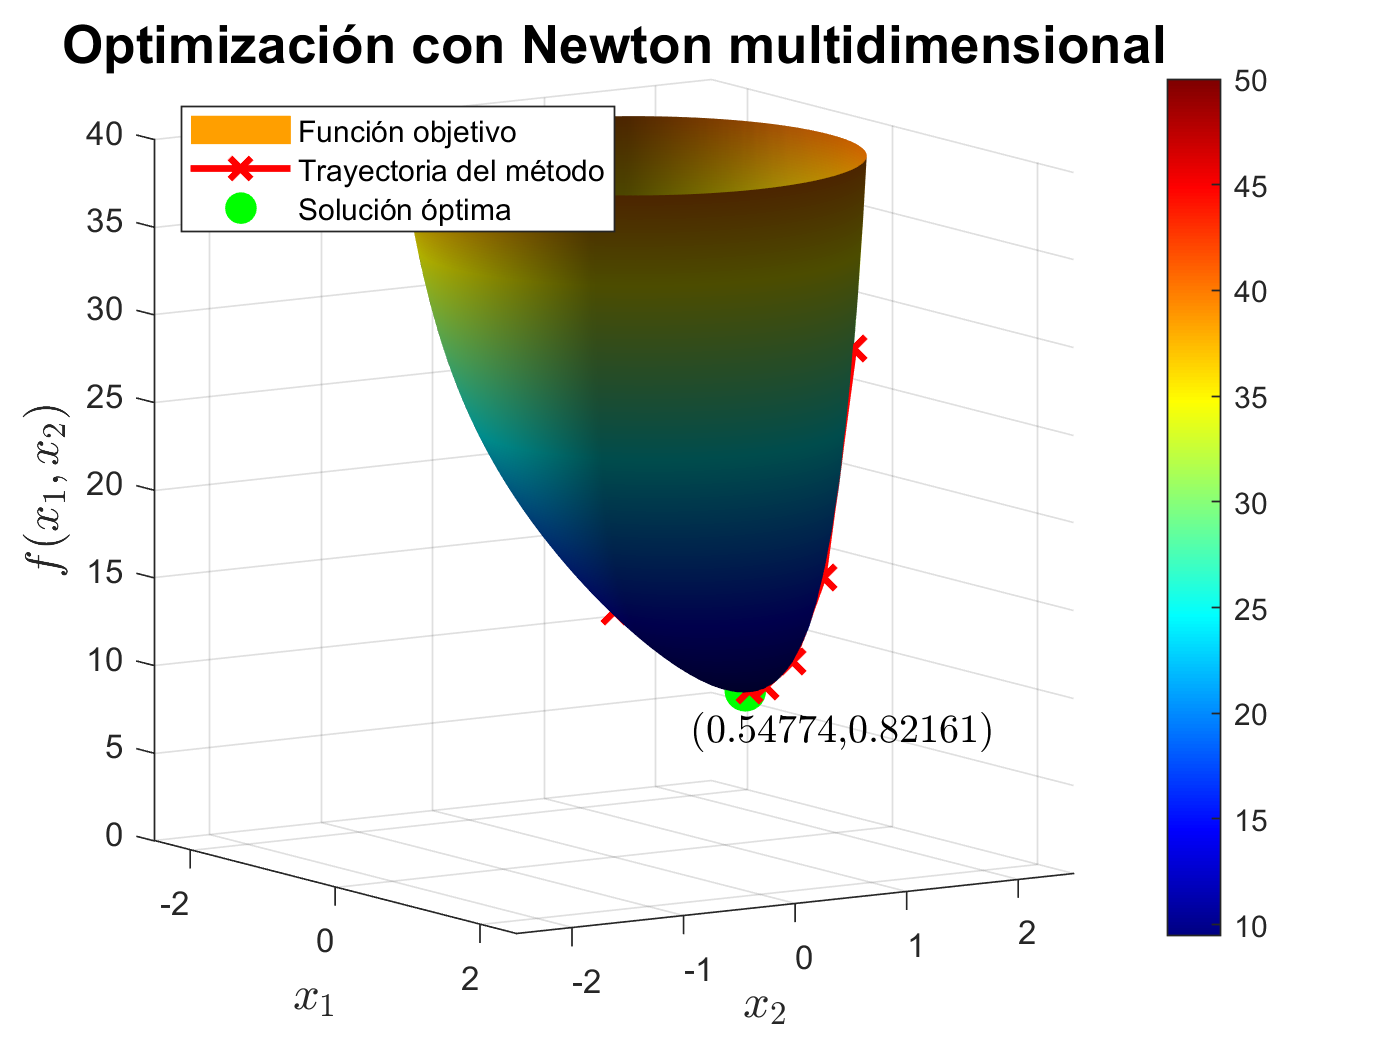


%% Paso 5: Visualización gráfica de la función objetivo y el proceso de optimización

% Crear una malla de puntos para graficar la superficie
[x1_vals, x2_vals] = meshgrid(-2.5:0.05:2.5, -2.5:0.05:2.5);
f_vals = (x1_vals - 2).^2 + (x2_vals - 3).^2 + exp(x1_vals.^2 + x2_vals.^2);

% Limitar los valores de la función para mejorar la visualización
f_vals(f_vals > 50) = 50;  % Limitar el valor máximo de f(x_1, x_2) para que se vea mejor la superficie

% Graficar la función objetivo
figure;
surf(x1_vals, x2_vals, f_vals, 'EdgeColor', 'none');
hold on;

% Añadir detalles gráficos
shading interp;
colormap(jet);
colorbar;
lighting phong;
camlight headlight;
view([57 9]);  % Ajustar el ángulo de la vista

% Ajustar los límites de los ejes para mejorar la visualización
xlim([-2.5, 2.5]);
ylim([-2.5, 2.5]);
zlim([0, 40]);  % Limitar el eje z para una mejor visualización de la superficie

% Calcular los valores de f(x_1, x_2) en cada punto de la trayectoria
f_trayectoria = arrayfun(@(i) f(x_hist(i, :)'), 1:size(x_hist, 1));

% Graficar la trayectoria del método de Newton en la superficie
plot3(x_hist(:,1), x_hist(:,2), f_trayectoria, 'rx-', 'MarkerSize', 10, 'LineWidth', 2);

% Graficar el punto final (solución óptima)
plot3(x_k(1), x_k(2), f(x_k), 'go', 'MarkerSize', 12, 'MarkerFaceColor', 'g');

% Marcar la solución óptima en el gráfico
text(x_opt(1), x_opt(2) - 0.5, fval - 2, ['(', num2str(x_opt(1)), ',', num2str(x_opt(2)), ')'], ...
    'FontSize', 12, 'Interpreter', 'latex', 'Color', 'black', 'FontWeight', 'bold');

% Etiquetas y leyenda
xlabel('$x_1$', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('$x_2$', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
zlabel('$f(x_1, x_2)$', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
title('Optimización con Newton multidimensional', 'FontSize', 16, 'FontWeight', 'bold');
legend({'Función objetivo', 'Trayectoria del método', 'Solución óptima'}, 'Location', 'northwest');
grid on;
hold off;

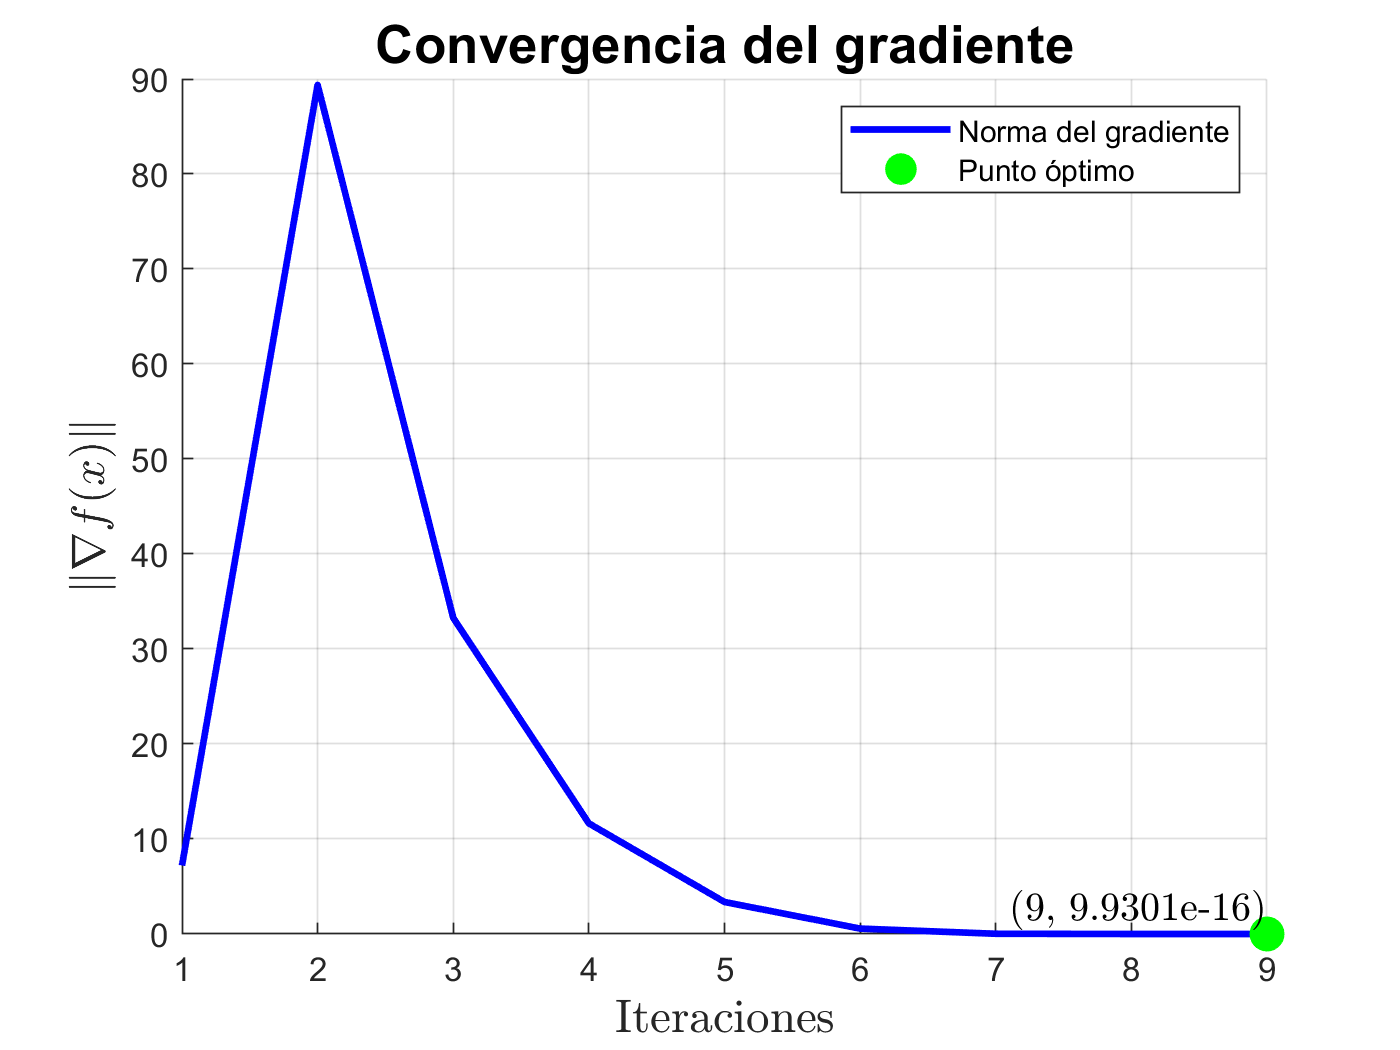


%% Paso 6: Graficar el gradiente en cada iteración

figure;
hold on;

% Calcular la norma del gradiente en cada iteración
norm_grad_hist = zeros(iter, 1);  % Inicializar el historial de normas del gradiente
for i = 1:iter
    norm_grad_hist(i) = norm(grad_f(x_hist(i, :)'));
end

% Graficar el valor de la norma del gradiente en cada iteración
plot(1:iter, norm_grad_hist, 'b-', 'LineWidth', 2);

% Etiquetar el punto óptimo en el gráfico
plot(iter, norm(grad_f(x_opt)), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
text(iter, norm(grad_f(x_opt)), ['(', num2str(iter), ', ', num2str(norm(grad_f(x_opt))), ')'], ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 12, 'Interpreter', 'latex');

% Añadir etiquetas y detalles del gráfico
xlabel('Iteraciones', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('$\|\nabla f(x)\|$', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
title('Convergencia del gradiente', 'FontSize', 16, 'FontWeight', 'bold');

% Añadir leyenda
legend({'Norma del gradiente', 'Punto óptimo'}, 'Location', 'northeast');

% Mostrar cuadrícula
grid on;
hold off;